clear;
clc;

## Objective

times = 0:0.1:1;
len = size(times, 2);
force_square_obj = @(u) trapz(times,u.^2);
absolute_work = @(u) trapz(times, abs(u.*cumtrapz(times,u)));

## Formulation

LB = ones(len, 1)*(-inf); %Lower Bounds
UB = ones(len, 1)*(inf); %Upper Bounds

X0 = zeros(len, 1); %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 100000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

pos_target = 1;

## Solve NLP

[X, Cost] = fmincon(@(x) force_square_obj(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) single_shooting_constraints(x, times, pos_target), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          12    0.000000e+00     1.000e+00     1.000e+00     0.000e+00     1.490e-09  
    1          24    1.323077e+01     1.849e-08     1.000e+00     1.194e+01     4.563e+00  
    2          36    1.306560e+01     1.678e-09     1.000e+00     4.172e-01     2.434e-01  
    3          48    1.257346e+01     1.948e-10     1.000e+00     1.849e+00     1.049e-01  
    4          60    1.246106e+01     1.406e-09     1.000e+00     1.402e+00     3.465e-07  

Optimization completed: The relative first-order optimality measure, 3.464516e-07,
is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint
violation, 1.

## Plot

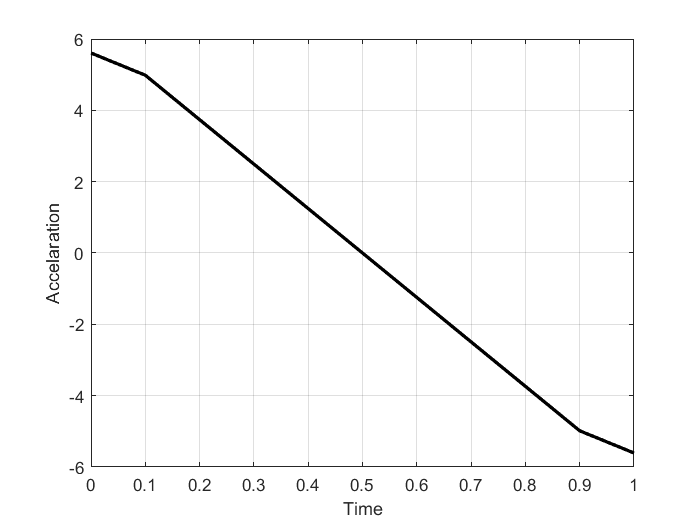

vels = cumtrapz(times, X);
poss = cumtrapz(times, vels); 

figure(1);
plot(times, X,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Accelaration');

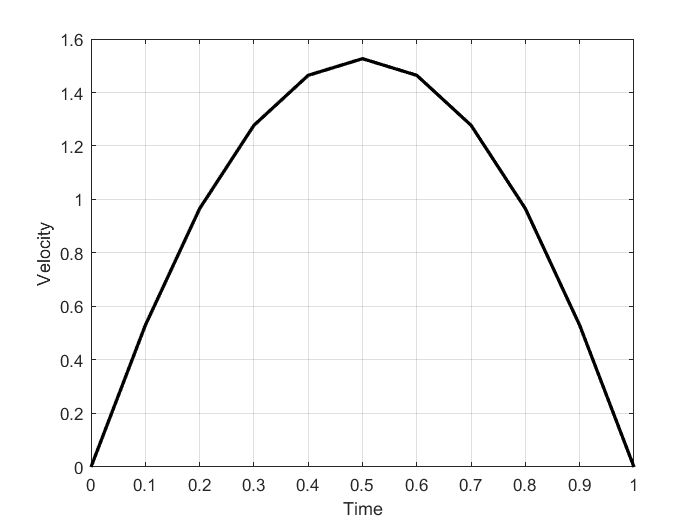


figure(2);
plot(times, vels,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Velocity');

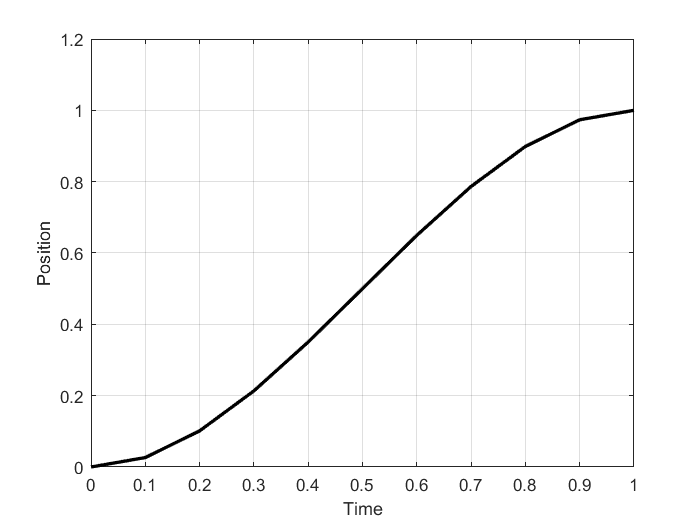


figure(3);
plot(times, poss,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Position');